clc;
clear;
close all;

## Dati di specifica

Dati di specifica per un trasformatore trifase a colonne, con collegamento stella-stella.

Pn = 650; % kVA
Vn2 = 6000; % V (Alta Tensione - AT)
Vn1 = 400; % V (Bassa Tensione - BT)
Vcc = 4; % Tensione di cortocircuito %
f = 60; % Hz
eta = 0.978; % Rendimento
COL1 = 1;
COL2 = 1;

## Distanze di isolamento

% Calcolo dei valori minimi
x_min = 25 + 1.26 * Vn2*10^(-3);
y_min = 40 + 1.7 * Vn2*10^(-3);
z_min = 0.85 * Vn2*10^(-3);

KS = 1.9; % Coefficiente di sicurezza

% Determinazione dei valori effettivi
x = arrotonda_al_multiplo_di_5(x_min*KS);
y = arrotonda_al_multiplo_di_5(y_min*KS);
z = arrotonda_al_multiplo_di_5(z_min*KS);

% Battente d'olio tra giogo superiore e coperchio
hb_sup = 270; % mm

% Battente d'olio tra giogo inferiore e fondo
hb_inf = 50; % mm

## Dimensionamento della colonna

In quanto trasformatore monofase a due colonne è stato scelto K = 1.35,

Un valore di induzione di colonna di primo tentativo di B_c = 1.55 [T]

K = 1.4;
Phi_p = K * sqrt(Pn / f)* 10^-2; % Flusso di colonna primo tentativo (Wb)
Bc_p = 1.6; % T (Induzione primo tentativo)
kst = 0.94; % Coefficiente di stipamento 
Scfe_p = Phi_p / Bc_p; % Sezione ferro di primo tentativo
Sc_p = Scfe_p / kst; % Sezione totale di primo tentativo
Sc_p_mm2 = Sc_p * 10^6; % Conversione in mm²
ku = 0.935; % Coefficiente di utilizzazione della colonna

% Diametro colonna
D = sqrt(4 * Sc_p / (pi * ku)); % Diametro colonna (m)

% Scelta numero gradini colonna e larghezza pacchetti
ngc = 5;
k = [0.950, 0.846, 0.707, 0.534, 0.313]; % Larghezza dei pacchetti in p.u.
c_ = (k * D * 1000); % Larghezza pacchetti (mm)
c = arrotonda_al_multiplo_di_5(c_); % Arrotondamento a multipli di 5 mm

% Altezza pacchetti
b_ = zeros(1, ngc);
b_(1) = sqrt((D * 1000)^2 - c(1)^2);
for i = 2:ngc
    b_(i) = (sqrt((D * 1000)^2 - c(i)^2) - (b_(1) + sum(2 * b_(2:i-1))) ) / 2;
end
b = round(b_); % Arrotondamento al mm

% Profondità colonna
L = sum([b(1), 2 * sum(b(2:end))]); % Altezza colonna in mm

% Calcolo delle sezioni dei pacchetti in mm²
Sp_mm2 = [c(1) * b(1), 2 * c(2) * b(2), 2 * c(3) * b(3), ...
          2 * c(4) * b(4), 2 * c(5) * b(5)];

% Conversione in cm² (1 cm² = 100 mm²)
Sp_cm2 = Sp_mm2 * 10^(-2);

% Sezione lorda della colonna in cm²
Sc = sum(Sp_cm2);

% Sezione della colonna di solo ferro
Scfe = Sc * kst;

## Progetto del Giogo

Giunti intercalati

% Coefficiente di sovradimensionamento della sezione del giogo
kg = 1.15;

% Determinazione delle larghezze dei pacchetti del giogo in mm
g_ = c * kg;
g = arrotonda_al_multiplo_di_5(g_); % Arrotondamento

% Altezza del giogo
Hg = g(1);

% Sezione lorda del giogo
Sg = Sc * kg; % cm^2

% Sezione del giogo di solo ferro
Sgfe = Scfe * kg;

## Flussi e induzioni di colonna e giogo

% Calcoli relativi alla tensione di fase e tensione di spira
% Tensione di fase nominale
Vf1 = Vn1 * sqrt(COL1 / 3); 

% Tensione di spira di primo tentativo
Vsp_p = sqrt(2) * pi * f * Bc_p * Scfe * 10^(-4);

% Numero di spire BT di primo tentativo
N1_p = Vf1 / Vsp_p;

% Definizione del numero di spire BT (arrotondato)
N1 = ceil(N1_p);

% Induzione di colonna effettiva
Bc = Vf1 / (sqrt(2) * pi * N1 * f * Scfe * 10^(-4));

% Flusso di colonna effettivo
Phi_c = Bc * Scfe * 10^(-6);

% Induzione effettiva nel giogo
Bg = (Bc * Scfe) / Sgfe;

% Tensione di spira effettiva
Vsp = Vf1 / N1;

## Altezza avvolgimento

In1 = (Pn * 1000) / (sqrt(3) * Vn1); % Corrente nominale (A)

If1 = In1 * sqrt(1 / COL1);

Ai = 350; % Densità lineare corrente (A/cm)

h = arrotonda_al_multiplo_di_5((N1 * In1) / Ai * 10); % Altezza colonna (mm)

## Avvolgimento BT

V_n1 < 700 V, I_n1 < 2000 A -> avvolgimento a strati

sigma1_p = 4; % Densità corrente primo tentativo (A/mm²)
Ssp1_p = If1 / sigma1_p; % Sezione spira primo tentativo (mm²)
a1 = 5.6; % Larghezza piattina BT (mm)
b1 = 9; % Altezza piattina BT (mm)
Sc1 = 49.5; % Sezione netta piattina (mm²)
bis1 = 0.59; % Bispessore isolamento (mm)

Ncs1 = ceil(Ssp1_p / Sc1); % Numero piattine in parallelo
Ssp1 = Ncs1 * Sc1; % Sezione effettiva spira (mm²)

% Scelgo m1 tra i divisori di N1
divisori_N1 = trovaDivisori(N1);% Numero di piattine in senso radiale
m1 = 2; % Numero di piattine in senso radiale

% Numero di piattine sovrapposte in senso assiale
n1 = Ncs1 * (N1 / m1);

% Densità effettiva di corrente
sigma1 = If1 / Ssp1;

% Altezza calcolata dell'avvolgimento
h_primo = (b1 + bis1) * Ncs1 * (N1 / m1 + 1);

% Errore rispetto all'altezza determinata
errore_h1 = abs(h - h_primo) / h * 100;

h1 = h; % è possibile compensare l'errore in fase di corstruzione 

% Distanza tra avvolgimenti
aca = 8; % mm (canale assiale)
acart = 4; % mm (spessore cartoccio)
ais = 0.5; % mm (spessore isolamento assiale)
theta1 = m1 * (a1 + bis1) + (m1 + 2) * ais + aca; % Dimensione assiale avvolgimento
D1i = D * 1000 + 2 * acart; % Diametro interno avvolgimento
D1e = D1i + 2 * theta1; % Diametro esterno avvolgimento
theta_ = aca + acart; % mm distana tra avvolfimento AT e BT
theta = 18.3; % mm impostato successivamente alla fase di calcolo

## Avvolgimento AT

Vf2 = Vn2 * sqrt(COL2 / 3);
N2_p = (Vf2 / Vsp);
N2 = round(N2_p);
In2 = (Pn * 1000) / (sqrt(3) * Vn2);
If2 = In2 * sqrt(1 / COL2);

% Sezione spira AT
sigma2_p = 4; % A/mm²
Ssp2_p = If2 / sigma2_p % Sezione spira AT (mm²)

Ssp2_p = 15.6366

a2 = 2.5; % mm
b2 = 7.1; % mm
Sc2 = 17.2; % mm²
bis2 = 0.55; % mm
Ncs2 = 1; % conduttori per spira 

% Scelgo m2 tra i divisori di N2
divisori_N2 = trovaDivisori(N2);
m2 = 10; % piattie affiancate in senso radiale

n2 = N2 / m2; % piattie affiancate in senso assiale

Ssp2 = Ncs2 * Sc2;% Sezione effettiva spira (mm²)

% Densità effettiva di corrente
sigma2 = If2 / Ssp2;


bcr = 9; % Altezza canale radiale di raffredddamento

h_ = h;
h_secondo = (b2 + bis2 + bcr) * (N2 / m2 + 1);

% Errore rispetto all'altezza determinata
errore_h2 = abs(h - h_secondo) / h * 100;

h2 = h; % è possibile compensare l'errore in fase di corstruzione 

% Calcolo dimensioni avvolgimento AT
theta2 = m2 * (a2 + bis2);
D2i = D1e + 2 * theta;
D2e = D2i + 2 * theta2;

% Interasse tra colonne e altezza trasformatore
X = D2e + z; % mm
H = h + 2 * x; % mm (altezza cassone)
a_col = c(1); % mm (larghezza colonna)

% Rapporto H/a_col
H_a_col = H / a_col % 2.5 - 4.5

H_a_col = 3.3590


% Rapporto X/a_col
X_a_col = X / a_col % 1.6 - 2.6

X_a_col = 1.8698


% Rapporto H/X
H_X = H / X % % 1.2 - 1.8

H_X = 1.7964


% Rapporto L/a_col
L_a_col = L / a_col % ca 1

L_a_col = 0.9897

## Dimensinamento cassone

% Altezza cassone
Hcass = H + 2 * Hg + hb_sup + hb_inf;

% Raggio avvolgimento di AT
R2e = D2e / 2;

% Raggio di curvatura superficie laterale cassone
Rcass = R2e + y;

% Perdite totali teoriche
Pt = Pn * (1 - eta) / eta;

% Superficie totale di scambio termico
S = 38 * Pt * 1000; % cm^2

% Altezza dell'aletta
ha = 250; % mm

% Perimetro interno del cassone, esclusa alettatura
Pi = 4 * X + 2 * pi * Rcass; % mm

% Sviluppo perimetrale del mantello, inclusa alettatura
L = S * 10^2 / Hcass; % mm

% Numero teorico di alette
N_primo = (L - Pi) / (2 * ha);

% Numero di alette
N = round(N_primo);

% Passo di alettatura
tau_a = Pi / N;

% Scelta rapporto b/a
k = 2.8;

% Larghezza aletta
a = tau_a / (1 + k);

% Distanza tra alette
b_aletta = a * k;

## Calcolo e Verifica

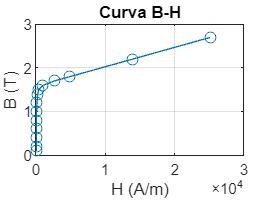

H_ = [35, 46, 62, 72, 89, 107, 140, 240, 400, 1000, 2650, 4900, 13900, 25150]; % A/m
B = [0.1, 0.2, 0.4, 0.6, 0.8, 1, 1.2, 1.4, 1.5, 1.6, 1.7, 1.8, 2.2, 2.7]; % T

% Plotting della curva B-H
plot(H_, B, '-o');
xlabel('H (A/m)');
ylabel('B (T)');
title('Curva B-H');
grid on;

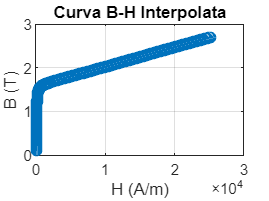



% Calcolo dell'interpolante cubica della curva H-B:
vs = spline(B, H_); 
y = @(x) ppval(vs, x);

% Generazione di punti per la curva interpolata
B_interp = linspace(min(B), max(B), 500);
H_interp = y(B_interp);

% Plotting della curva interpolata
plot(H_interp, B_interp, '-o');
xlabel('H (A/m)');
ylabel('B (T)');
title('Curva B-H Interpolata');
grid on;


% Calcolo del campo H nella colonna e nel giogo:
Bc_ = Bc; % T
Hc = y(Bc_); % A/m

Bg_ = Bg; % T
Hg = y(Bg_); % A/m

% Calcolo del campo H nel traferro (equivalente):
mu0 = 4 * pi * 10^(-7); % H/m
Ha = Bc / mu0; % A/m

Lg = X + Hg / 2; % Lunghezza tratto circuito magnetico nel giogo (mm)

Lc = H; % Lunghezza tratto circuito magnetico colonna (mm)

La = 0.035;  % Lunghezza tratto circuito magnetico traferro (mm) (giunti intercalati)

AStot = (Hc * Lc * 10^-3 + Hg * Lg * 10^-3 * (4/3) + 2 * Ha * La * 10^-3); % Amperspire medie totali per fase (A)

Im = AStot / (sqrt(2) * N1); % Corrente magnetizzante di fase (A)

Im_percent = (Im / If1) * 100 % Percentuale corrente magnetizzante (%)

Im_percent = 2.3608

## Perdite nel ferro

% Densità del nucleo laminato (kg/mm^3)
gamma_lam = 7.65e-6; 

% Massa delle colonne (kg) (Sc in cm^2)
Gc = 3 * Sc * 10^2 * H * gamma_lam; % Sc: sezione colonna (mm^2), H: altezza colonna (mm)

% Massa dei gioghi in zona non comprendente giunti (kg) (Sg in cm^2)
Gg1 = 4 * X * Sg * 10^2 * gamma_lam; % X: interasse colonne (mm), Sg: sezione giogo (mm^2)

% Massa dei gioghi in zona giunti (kg)
Gg2_A = b(1) * c(1) / 2 * g(1) + 2 * b(2) * c(2) / 2 * g(2) + 2 * b(2) * c(2) / 2 * g(2) + 2 * b(3) * c(3) / 2 * g(3); % b, c: dimensioni pacchetti (mm), g: larghezza pacchetti giunto (mm)
Gg2_B = 2 * b(4) * c(4) / 2 * g(4) + 2 * b(5) * c(5) / 2 * g(5); 
Gg2 = 4 * (Gg2_A + Gg2_B) * gamma_lam; % kg

% Massa dei gioghi:
Gg = Gg1 + Gg2; % kg

% Massa del nucleo magnetico
Gfe = Gc + Gg; % kg

% Perdite specifiche in giogoo e colonna (da curva perdite a 50 Hz)
Bc_  % T

Bc_ = 1.5560

ps_c = 1.1; % W/kg  % Valore da curva perdite per Bc

Bg_ % T

Bg_ = 1.3531

ps_g = 0.8; % W/kg  % Valore da curva perdite per Bg

% Coefficiente di lavorazione
kL = 1.1;

% Coefficiente di maggiorazione delle perdite nella zona giunti
km = 1.5;

% Perdite nel ferro (isteresi + correnti parassite)
Pfe = (ps_c * Gc + ps_g * Gg1 + km * ps_g * Gg2) * kL; % W

## Perdite nel rame

% Calcolo dei diametri medi degli avvolgimenti
D1m = (D1i + D1e) / 2; % Diametro medio avvolgimento BT (mm)
D2m = (D2i + D2e) / 2; % Diametro medio avvolgimento AT (mm)

% Resistenza avvolgimenti in cc
r1cc = 0.021 * (pi * D1m * 10^-3) * N1 / Ssp1; % Resistenza avvolgimento BT (Ohm)
r2cc = 0.021 * (pi * D2m * 10^-3) * N2 / Ssp2; % Resistenza avvolgimento AT (Ohm)

% Altezza ridotta piattina BT
xi1 = 0.98 * a1 * 10^-1 * sqrt(n1 * b1 / h); % Altezza ridotta piattina BT

% Coefficiente di resistenza BT
kr1 = 1 + (m1^2 - 0.2) / 9 * xi1^4; % Coefficiente di resistenza BT

% Altezza ridotta piattina AT
xi2 = 0.98 * a2 * 10^-1 * sqrt(n2 * b2 / h); % Altezza ridotta piattina AT

% Coefficiente di resistenza AT
kr2 = 1 + (m2^2 - 0.2) / 9 * xi2^4; % Coefficiente di resistenza AT

% Resistenze avvolgimenti in c.a. a 50 Hz
r1ca = r1cc * kr1; % Resistenza avvolgimento BT in c.a. (Ohm)
r2ca = r2cc * kr2; % Resistenza avvolgimento AT in c.a. (Ohm)

% Resistenza totale riportata sul lato BT
Rtot = r1ca + r2ca * (N1 / N2)^2; % Resistenza totale riferita al BT (Ohm)

% Perdite Joule a carico nominale
PJn = 3 * Rtot * If1^2; % Perdite Joule a carico nominale (W)

% Perdite Joule a vuoto
PJ0 = 3 * r1ca * Im^2; % Perdite Joule a vuoto (W)

% Corrente attiva nel funzionamento a vuoto
Ia = (PJ0 + Pfe) / (sqrt(3) * Vn1); % Corrente attiva a vuoto (A)

% Corrente a vuoto
I0 = sqrt(Im^2 + Ia^2); % Corrente a vuoto (A)

## Rendimento

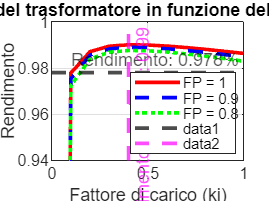

% Rapporto perdite
rapporto_perdite = PJn / Pfe;

% Corrente di rendimento massimo (p.u.)
I_rend_max = sqrt(Pfe / PJn);

% Funzione per il calcolo del rendimento
% ki: fattore di carico (I/In)
% FP: fattore di potenza
rendimento = @(ki, FP) (Pn * 10^3 * ki * FP) ./ (Pn * 10^3 * ki * FP + Pfe + PJn * ki.^2);

% Plottaggio del rendimento in funzione del fattore di carico ki
ki = 0:0.1:1; % Vettore dei fattori di carico da 0 a 1 con passo 0.1
% Plot del rendimento per diversi fattori di potenza
figure; % Crea una nuova figura
plot(ki, rendimento(ki, 1), '-r', 'LineWidth', 2, 'DisplayName', 'FP = 1'); % FP = 1 (carico resistivo)
hold on; % Mantiene il grafico corrente
plot(ki, rendimento(ki, 0.9), '--b', 'LineWidth', 2, 'DisplayName', 'FP = 0.9'); % FP = 0.9 (carico induttivo)
plot(ki, rendimento(ki, 0.8), ':g', 'LineWidth', 2, 'DisplayName', 'FP = 0.8'); % FP = 0.8 (carico induttivo)

% Aggiungi retta orizzontale per rendimento eta
yline(eta, '--k', 'LineWidth', 2, 'Label', sprintf('Rendimento: %.3f%%', eta));

% Trova il valore massimo del rendimento e il relativo ki
[rend_max, index_max] = max(rendimento(ki, 1)); % Considera solo la curva con FP = 1 per il massimo
ki_max = ki(index_max);

% Aggiungi retta verticale per rendimento massimo
xline(ki_max, '--m', 'LineWidth', 2, 'Label', ['Rendimento Massimo: ', num2str(rend_max, '%.2f')]);

xlabel('Fattore di carico (ki)'); % Etichetta asse x
ylabel('Rendimento'); % Etichetta asse y (senza percentuale)
title('Rendimento del trasformatore in funzione del fattore di carico'); % Titolo del grafico
legend();
grid on; 
ylim([0.94 1]); 
legend('Location', 'southeast'); 
hold off; 

% Costante di permeabilità magnetica del vuoto
mu0 = 4 * pi * 10^-7; % H/m

% Induttanza di dispersione totale riferita al lato BT (H)
Ld = (mu0 / h) * pi * (D1m) * N1^2 * (theta1 / 3 + theta + theta2 / 3) * 10^-3;

% Reattanza di dispersione (Ohm)
Xtot = Ld * 2 * pi * f;

% Impedenza base (Ohm)
Zb = Vn1 / (sqrt(3) * In1);

% Impedenza di corto circuito (Ohm)
Zcc = sqrt(Rtot^2 + Xtot^2);

% Tensione di corto circuito (%)
Vcc_percent = (Zcc / Zb) * 100

Vcc_percent = 3.9951

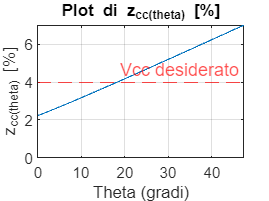


% Funzione per il calcolo della tensione di corto circuito al variare di theta
z_cc = @(theta) sqrt(Rtot^2 + ((mu0 / h) * pi * D1m * N1^2 * (theta1 / 3 + theta + theta2 / 3) * 10^-3 * 2 * pi * f)^2) / Zb * 100;

% Plot della funzione z_cc(theta)
theta_values = 0:0.1:50; % Valori di theta da 0 a 50 con passo 0.1
z_cc_values = arrayfun(z_cc, theta_values); % Calcola i valori di z_cc per ogni theta

plot(theta_values, z_cc_values);
title('Plot di z_cc(theta) [%]');
xlabel('Theta (gradi)');
ylabel('z_cc(theta) [%]');
ylim([0 7]);
grid on;

% Aggiunta della linea orizzontale a Vcc desiderato.
Vcc_desiderato = Vcc;
yline(Vcc_desiderato,'r--','Vcc desiderato');


%Trova i punti di intersezione.
indici = find(abs(z_cc_values - Vcc_desiderato) < 0.01);
intersezioni_theta = theta_values(indici);
intersezioni_vcc = z_cc_values(indici);
disp(['Intersezioni a theta = ', num2str(intersezioni_theta)]);

Intersezioni a theta = 18.3         18.4


## VERIFICA TERMICA DEL TRASFORMATORE

% **1. Stima ∆T medio del rame rispetto all'olio**

% Coefficienti di ricoprimento per canali assiali e radiali
k_ric_ass = 0.85; % Coefficiente di ricoprimento per canali assiali
k_ric_rad = 0.75; % Coefficiente di ricoprimento per canali radiali

% Superficie di dispersione termica equivalente per l'avvolgimento di BT (m^2)
Sdisp1 = 2 * pi * (D1m * 10^-3) * (h * 10^-3) * k_ric_ass; % (m^2)
% D1m: diametro medio avvolgimento BT (mm), h: altezza avvolgimenti (mm)

% Superficie di dispersione termica equivalente per l'avvolgimento di AT (m^2)
Sdisp2 = 2 * (b2 * 10^-3) * n2 * pi * (D2m * 10^-3) * k_ric_ass + 2 * n2 * pi * (D2m * 10^-3) * (theta2 * 10^-3) * k_ric_rad; % (m^2)
% b2: larghezza piattina AT (mm), n2: numero spire AT, D2m: diametro medio avvolgimento AT (mm), theta2: spazio tra avvolgimenti (mm)

% Flusso termico attraverso la superficie disperdente nell'avvolgimento di BT
q1 = (r1ca * If1^2) / Sdisp1; % (W/m^2)
% r1ca: resistenza avvolgimento BT (Ohm), If1: corrente nominale BT (A)

If2 = In2;
% Flusso termico attraverso la superficie disperdente nell'avvolgimento di AT (W/cm^2)
q2 = (r2ca * If2^2) / Sdisp2; % (W/m^2)
% r2ca: resistenza avvolgimento AT (Ohm), If2: corrente nominale AT (A)

% Coefficiente di scambio termico convettivo dell'olio per convezione naturale (W/(°C*m^2))
alpha_olio = 80; 

% Sovratemperatura media stimata del rame di BT rispetto all'olio (°C)
deltaT1 = q1 / alpha_olio;

% Sovratemperatura media stimata del rame di AT rispetto all'olio (°C)
deltaT2 = q2 / alpha_olio;

% **2. Stima ∆T massima dell'olio rispetto all'aria**

% Superficie disperdente del cassone che contribuisce all'irraggiamento (cm^2)
A = S * (tau_a / (2 * ha + tau_a)); % tau_a: passo alettatura (cm), ha: altezza aletta (cm)

% Flusso termico totale attraverso il cassone (W/m^2)
q = (PJn + Pfe) / (S * 10^-4); % PJn: perdite Joule nominali (W), Pfe: perdite nel ferro (W)

% Rapporto di irraggiamento
i = A / S;

% Sovratemperatura massima dell'olio rispetto all'aria (°C)
deltaT_max_olio_aria = 0.23 * q / (i + 0.8 + 0.001 * q) % < 50°C

deltaT_max_olio_aria = 35.1013


% **3. Stima ∆T media dell'olio rispetto all'aria**

% Stima della sovratemperatura media del cassone rispetto all'aria (°C)
deltaT_med_cass_aria = 0.13 * q / (i + 0.8);
% Stima della sovratemperatura media dell'olio rispetto all'aria (°C)
deltaT_med_olio_aria = (deltaT_max_olio_aria + deltaT_med_cass_aria) / 2;

% **4. Stima ∆T media del rame rispetto all'aria**

% Sovratemperatura media dell'avvolgimento sull'aria (°C) < 65°C con un certo margine (ca 10 gradi)
deltaTavv_aria_1 = deltaT_med_olio_aria + deltaT1 % BT 

deltaTavv_aria_1 = 50.3423

deltaTavv_aria_2 = deltaT_med_olio_aria + deltaT2 % AT

deltaTavv_aria_2 = 39.6484

function arrotondato = arrotonda_al_multiplo_di_5(numero)
  arrotondato = round(numero / 5) * 5;
end


function divisori = trovaDivisori(N)
  % Trova i divisori di un numero intero N.
  %
  % Input:
  %   N: Il numero intero di cui trovare i divisori.
  %
  % Output:
  %   divisori: Un vettore contenente i divisori di N.

  if ~isscalar(N) || ~isnumeric(N) || N ~= fix(N)
    error('Input deve essere un numero intero scalare.');
  end

  if N < 1
    error('Input deve essere un numero intero positivo.');
  end

  divisori = [];
  for i = 1:N
    if mod(N, i) == 0
      divisori = [divisori, i];
    end
  end
end